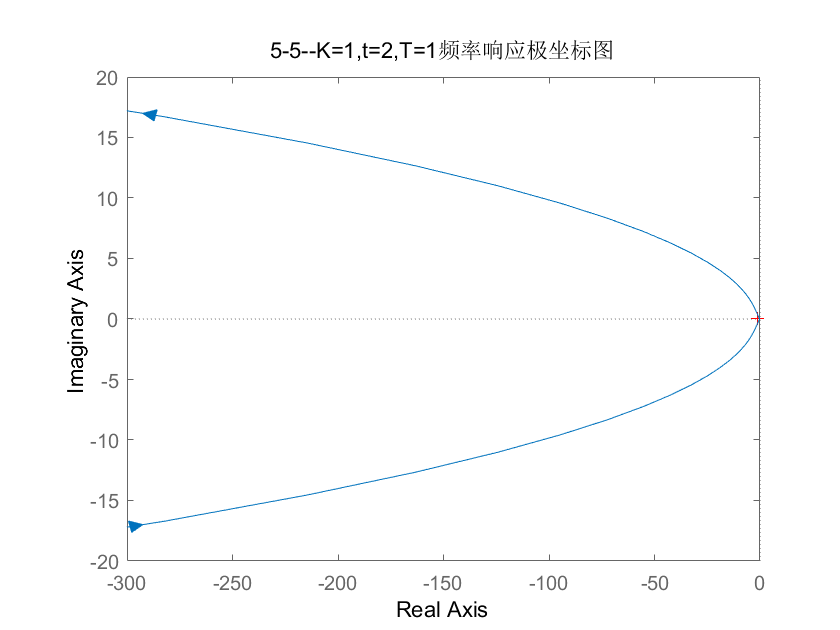

% 5-5
clear
K = 1;
t =2;
T = 1;
G1 = tf(K*[t 1],conv([1 0 0],[T 1]));
nyquist(G1),title('5-5--K=1,t=2,T=1频率响应极坐标图');

K =1,t =1,T =2;

K = 1

t = 1

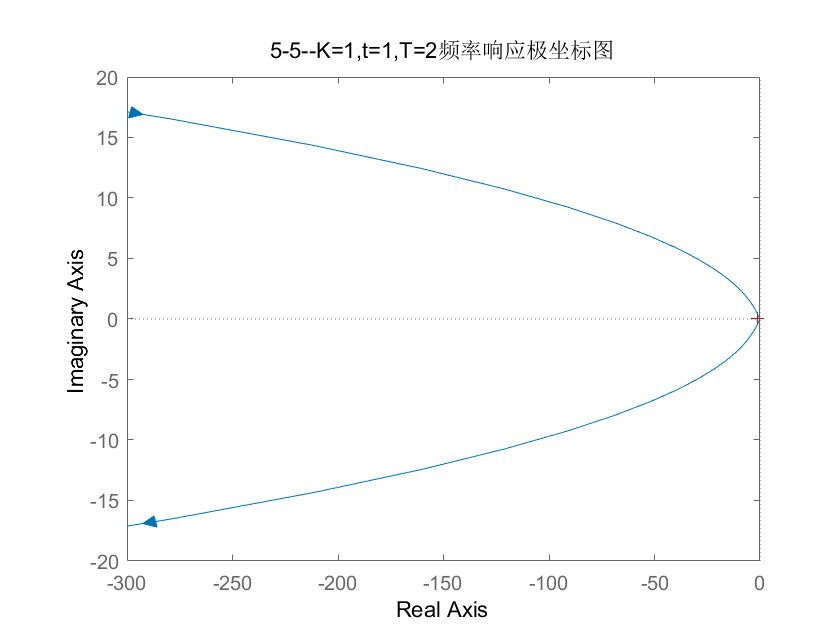

G2 = tf(K*[t 1],conv([1 0 0],[T 1]));
nyquist(G2),title('5-5--K=1,t=1,T=2频率响应极坐标图');

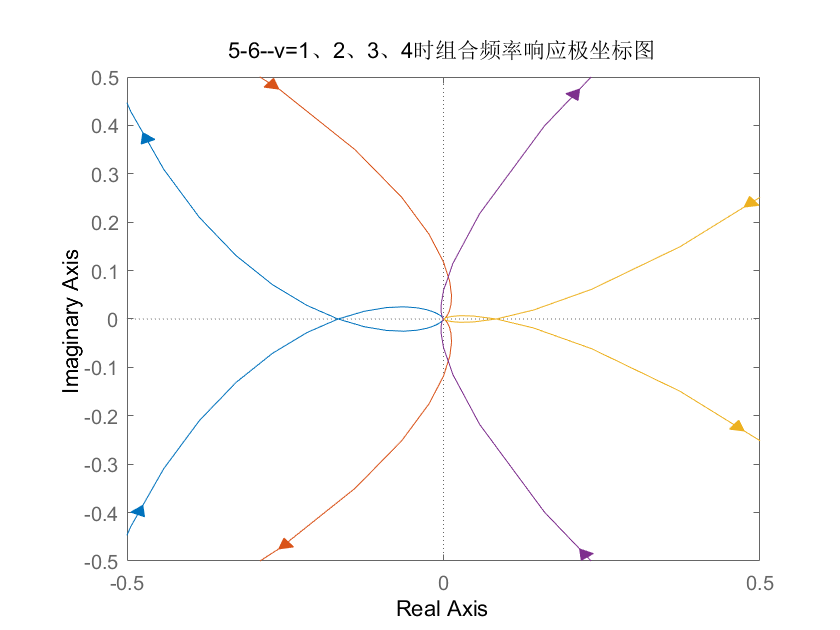

% 5-6
clear
num1 = [1];
den1 = [1 3 2 0];
den2 = [1 3 2 0 0];
den3 = [1 3 2 0 0 0];
den4 = [1 3 2 0 0 0 0];
nyquist(num1,den1),hold on;
nyquist(num1,den2);
nyquist(num1,den3),axis([-0.5 0.5 -0.5 0.5]);
nyquist(num1,den4),hold off,title('5-6--v=1、2、3、4时组合频率响应极坐标图');

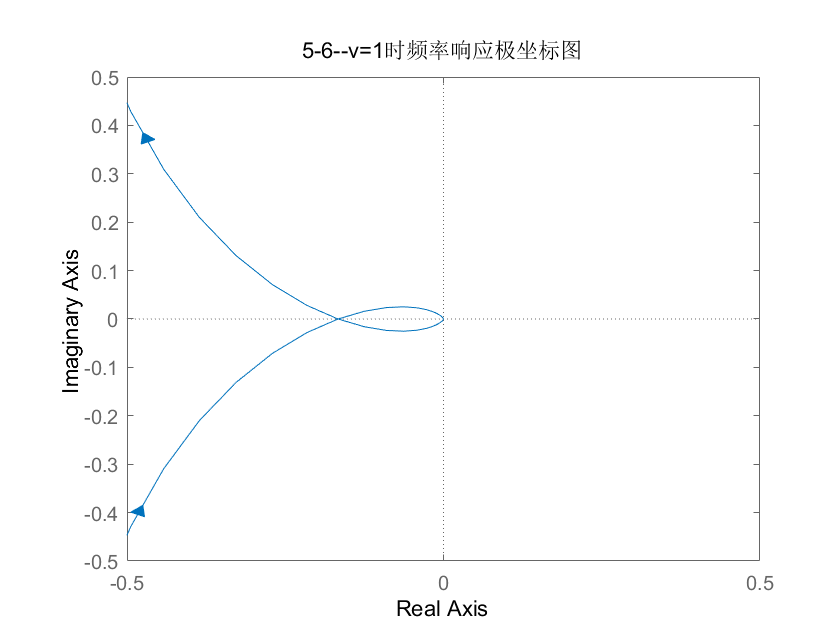

nyquist(num1,den1),title('5-6--v=1时频率响应极坐标图'),axis([-0.5 0.5 -0.5 0.5]);

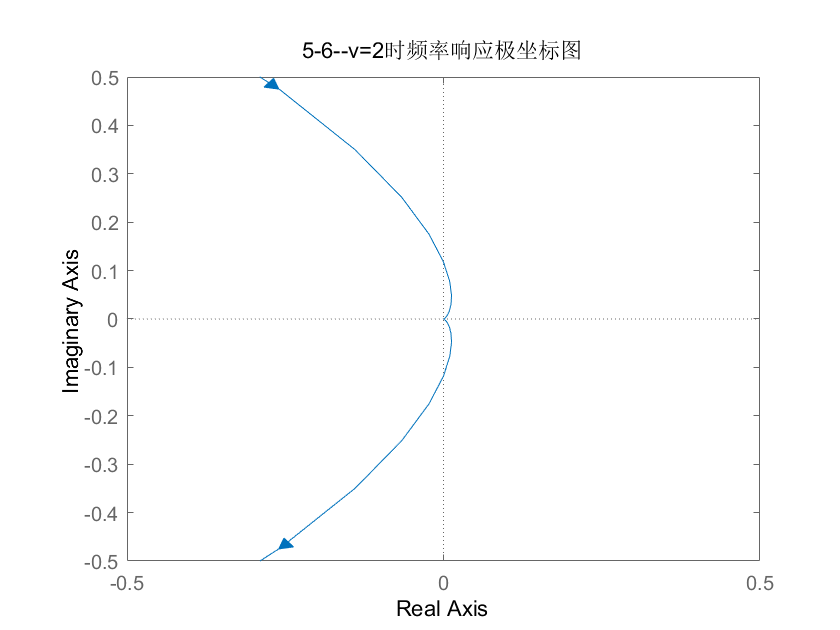

nyquist(num1,den2),title('5-6--v=2时频率响应极坐标图'),axis([-0.5 0.5 -0.5 0.5]);

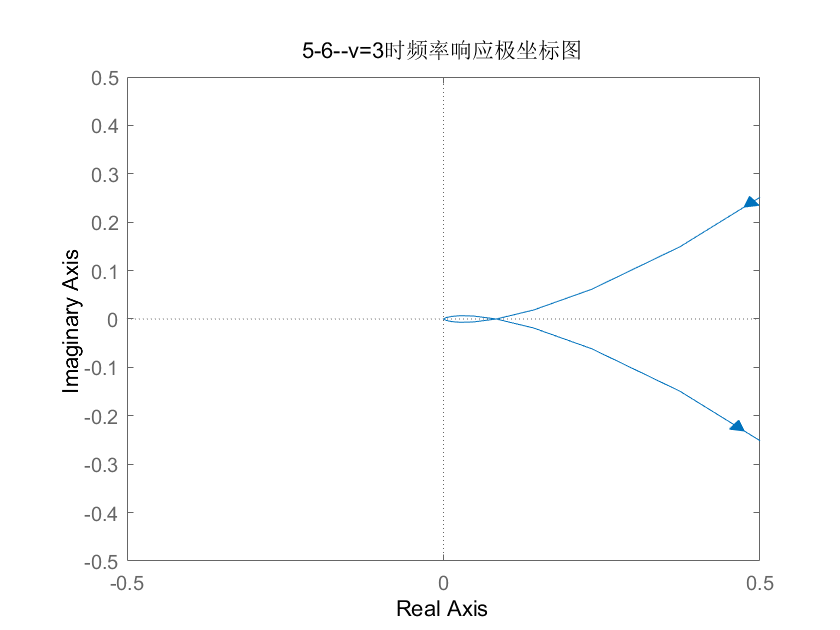

nyquist(num1,den3),title('5-6--v=3时频率响应极坐标图'),axis([-0.5 0.5 -0.5 0.5]);

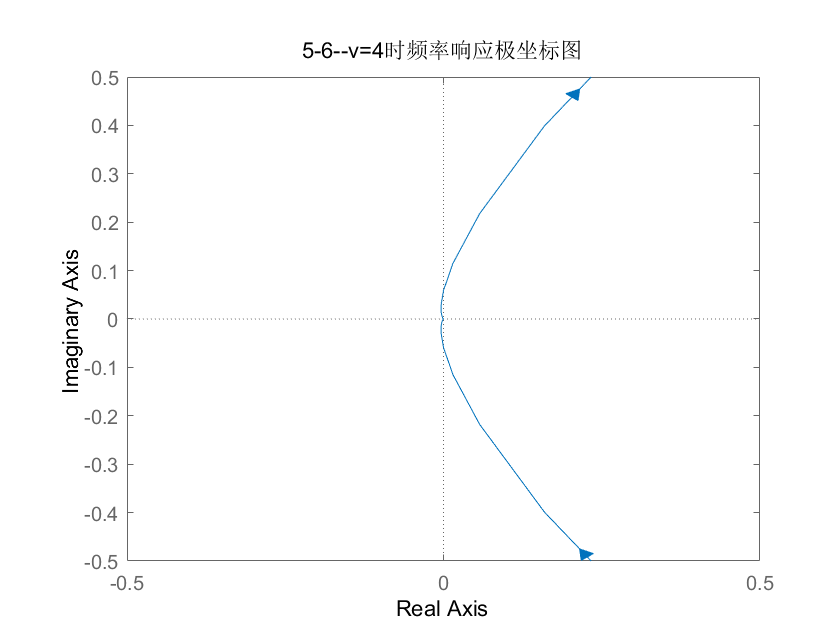

nyquist(num1,den4),title('5-6--v=4时频率响应极坐标图'),axis([-0.5 0.5 -0.5 0.5]);

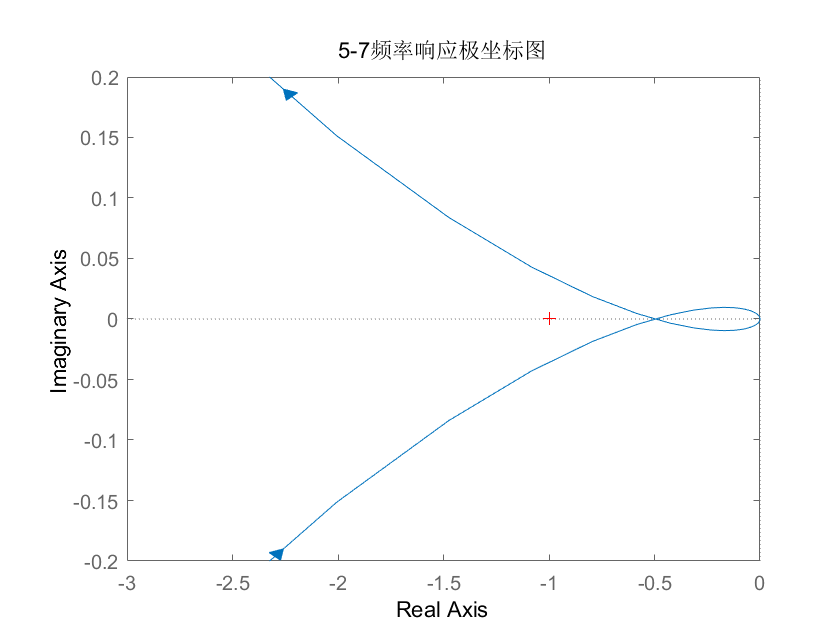

% 5-7
clear
K =10;
T1 = 20;
T2 = 0.05;
G = tf(K*[-T2,1],[T1,1,0]);
nyquist(G);
axis([-3,0,-0.2,0.2]);
title('5-7频率响应极坐标图')

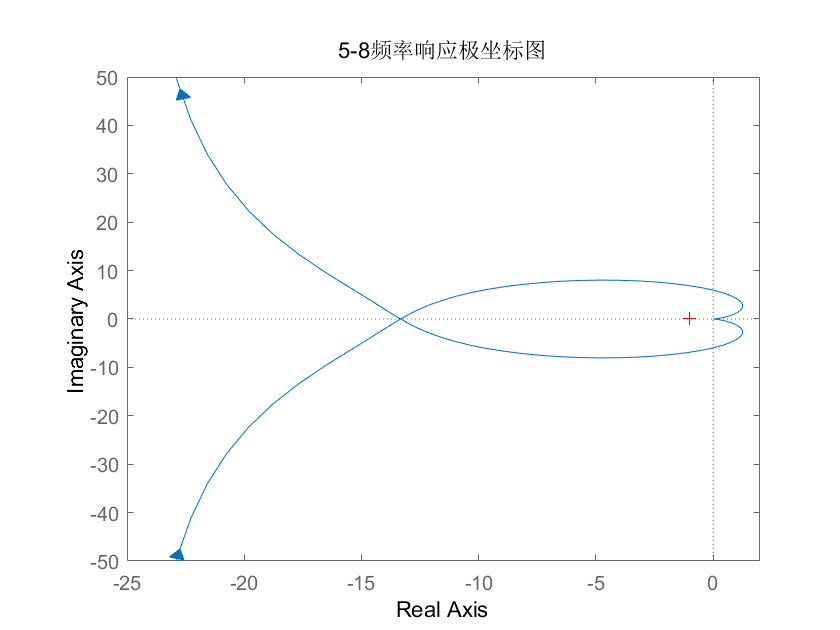

% 5-8
clear
G = tf(10,conv([2 1 0],[1 0.5 1]));
nyquist(G);
axis([-25 2 -50 50]);
title('5-8频率响应极坐标图')

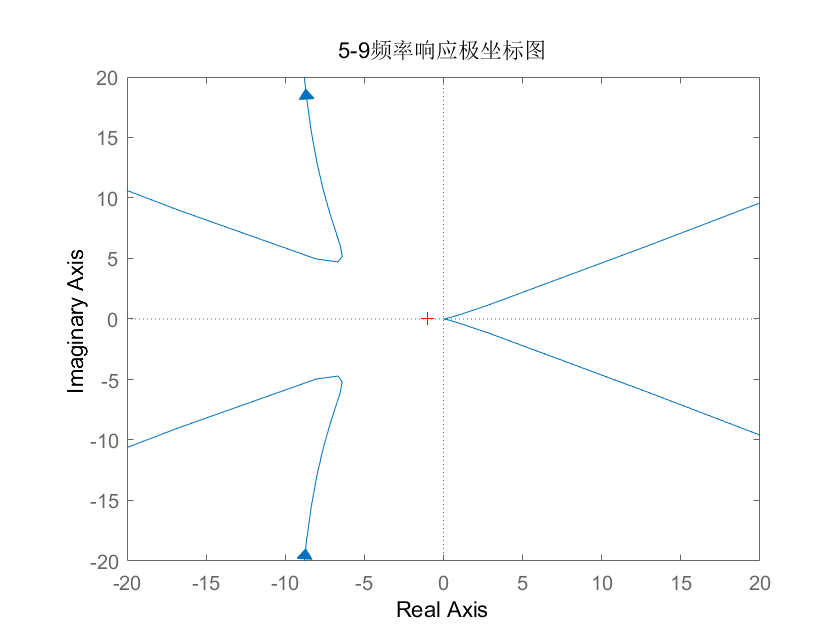

% 5-9
clear
G0 = tf([10],[0.25 0.25 1 1 0]);
nyquist(G0);
axis([-20 20 -20 20]);
title('5-9频率响应极坐标图');

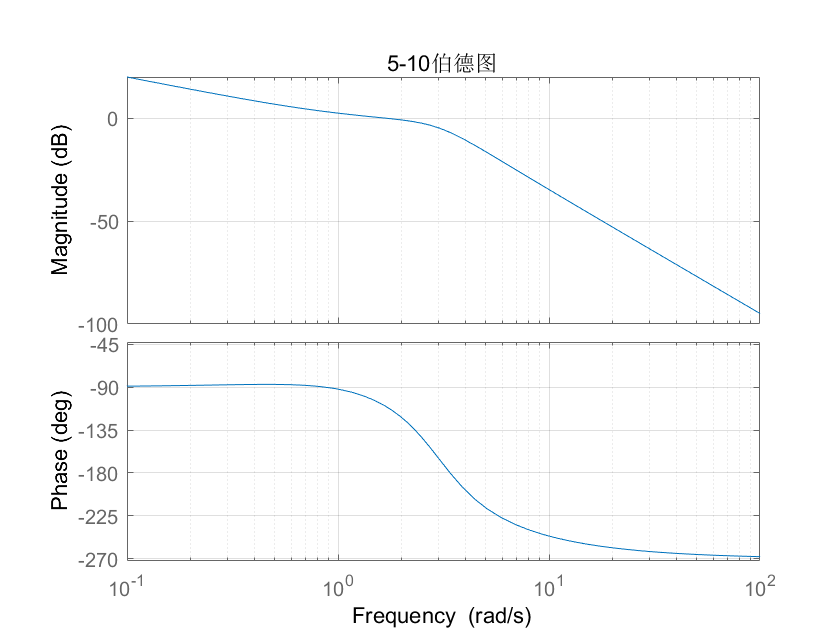

%5-10
clear
G = tf([1 1],conv([0.5 1 0],[1/9 1/3 1]));
bode(G),grid on,title('5-10伯德图');

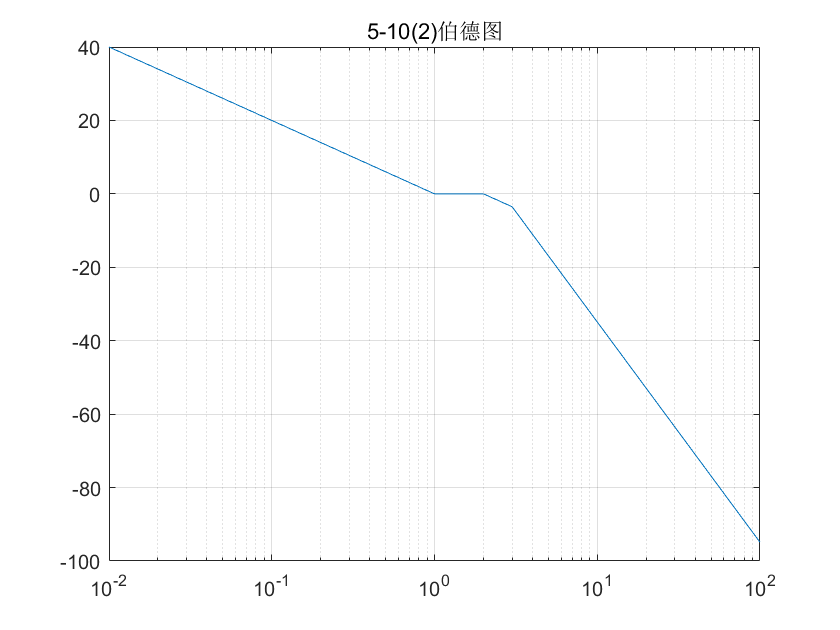


w = 10e-3:0.01:100;
[x,y] = bd_asymp(G,w); 
semilogx(x,y),grid on;
title('5-10(2)伯德图');

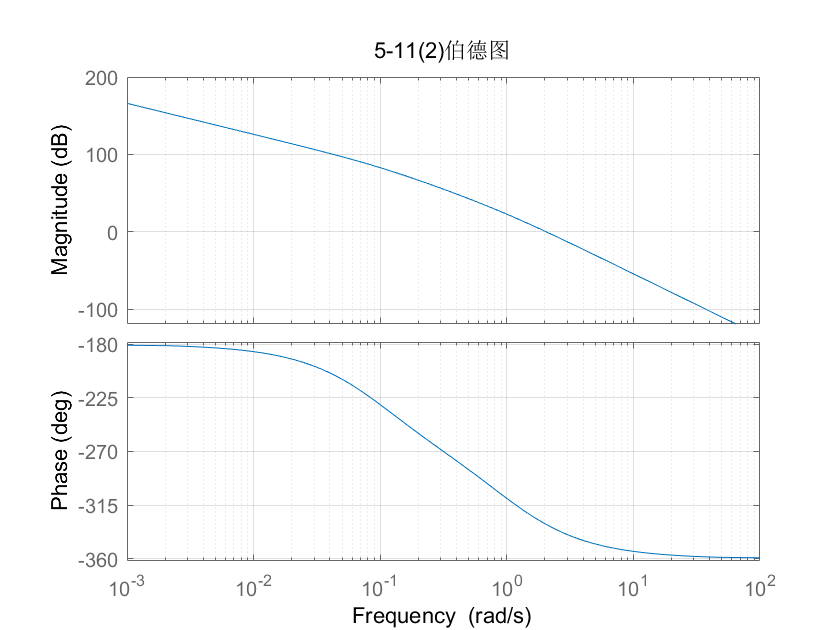

% 5-11
clear
G2 = tf([200],conv([1 1 0 0],[10 1]));
G3 = tf(8*[10 1],conv([1 1 1 0],[0.5 1]));
bode(G2),title('5-11(2)伯德图'),grid on;

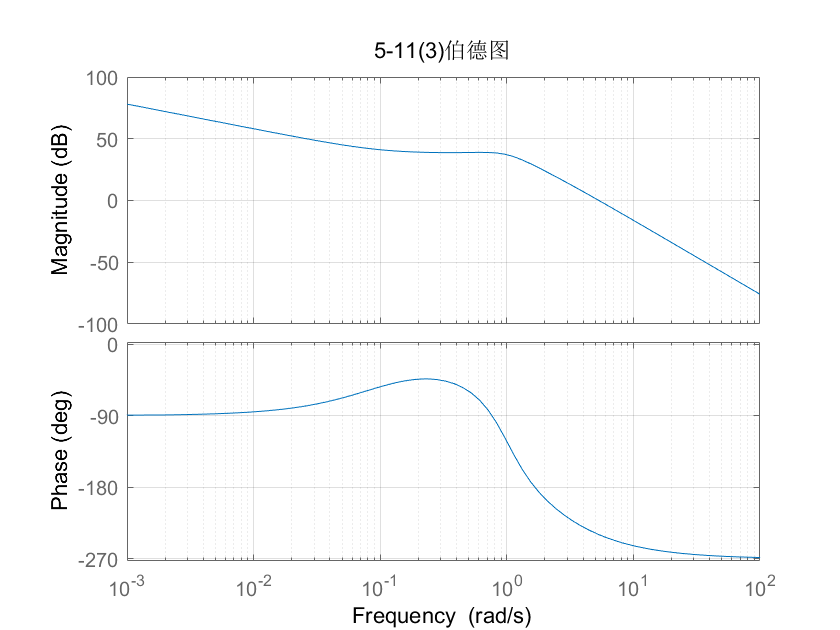

bode(G3),title('5-11(3)伯德图'),grid on;

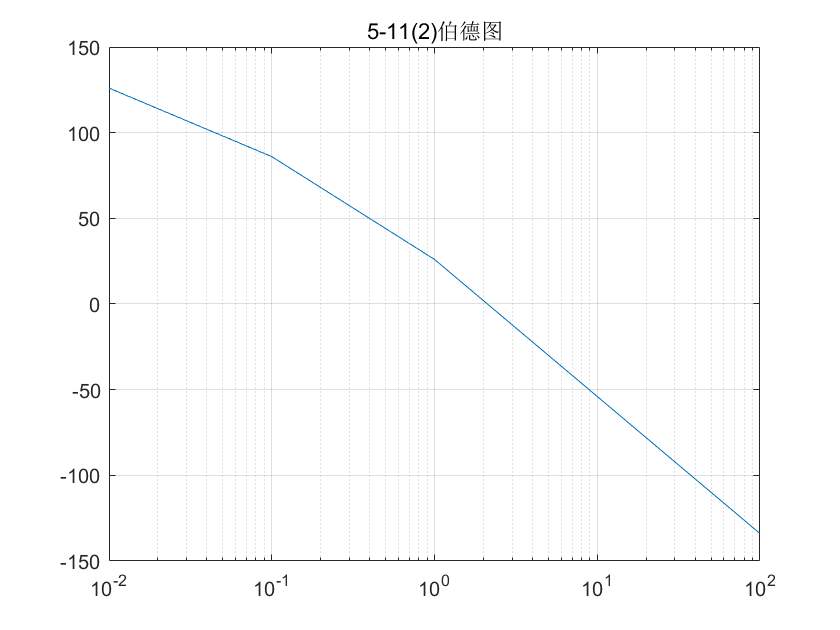


w = 10e-3:0.01:100;
[x2,y2] = bd_asymp(G2,w);
[x3,y3] = bd_asymp(G3,w);

semilogx(x2,y2),grid on;
title('5-11(2)伯德图');

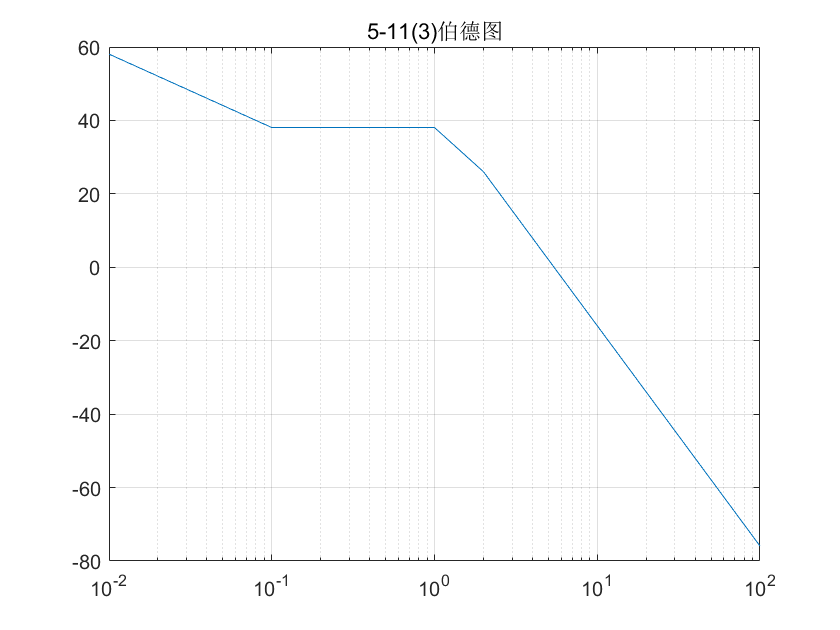


semilogx(x3,y3),grid on;
title('5-11(3)伯德图');

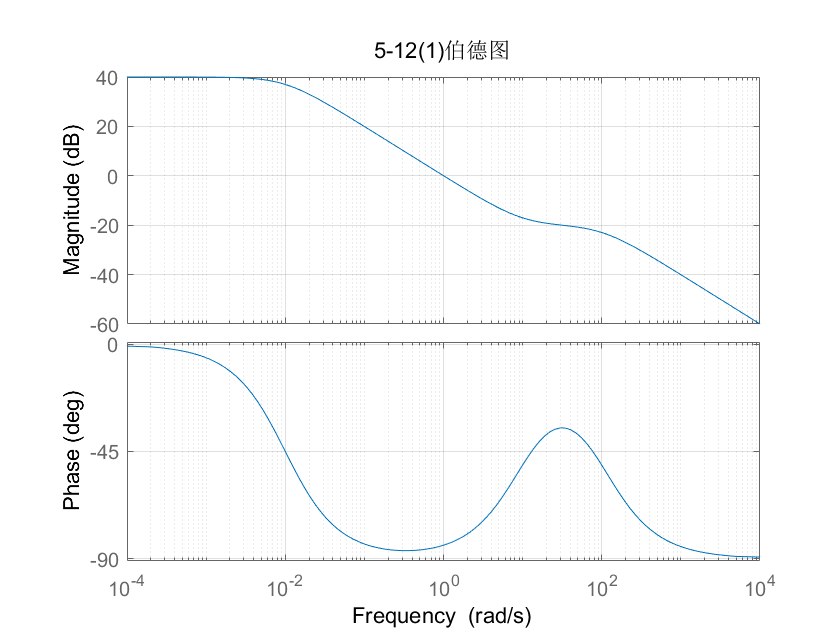

% 5-12
clear
G1 = tf(100*[0.1 1],[conv([100 1],[0.01 1])]);
G2 = tf([100/sqrt(10) 100],[conv([1 0 0],[1/(100*sqrt(10)) 1])]);
G3 = tf([10 0 0],[conv([1 0.1 1],[0.1 1])]);
bode(G1),title('5-12(1)伯德图'),grid on;

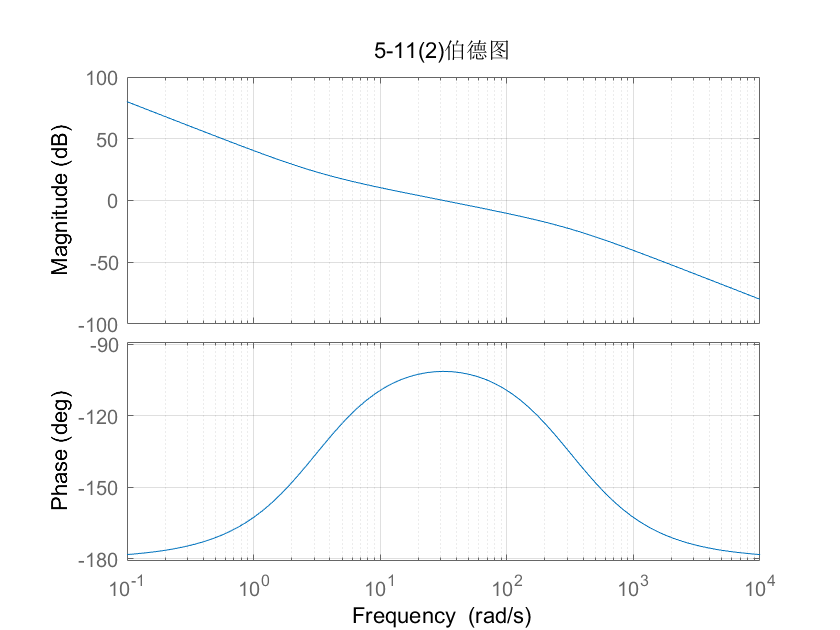

bode(G2),title('5-11(2)伯德图'),grid on;

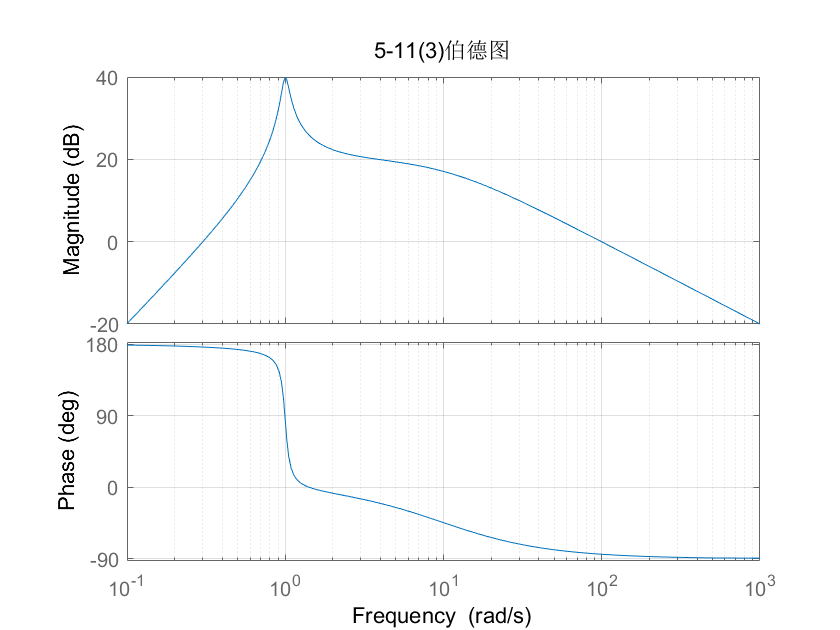

bode(G3),title('5-11(3)伯德图'),grid on;

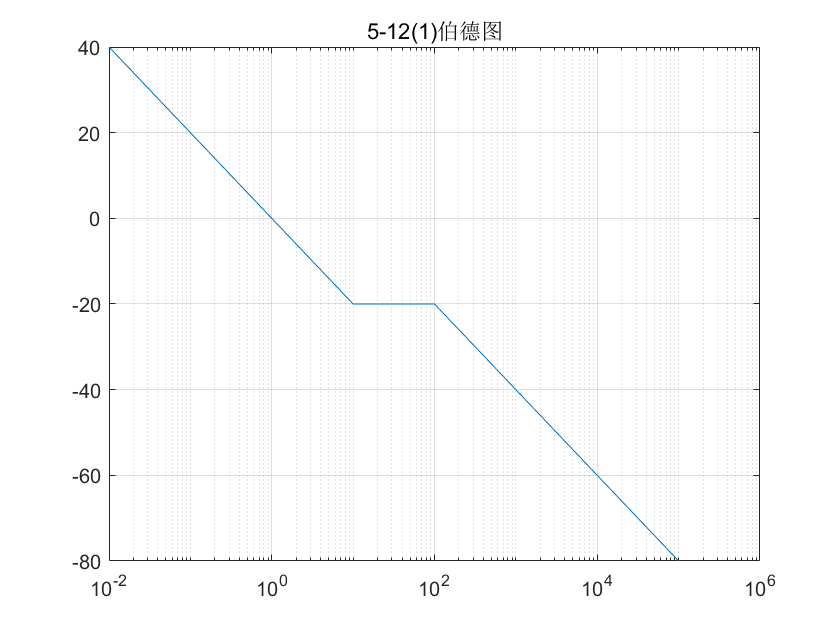


w = 10e-3:0.01:10e4;
[x1,y1] = bd_asymp(G1,w);
[x2,y2] = bd_asymp(G2,w);
[x3,y3] = bd_asymp(G3,w);
semilogx(x1,y1),grid on,title('5-12(1)伯德图');

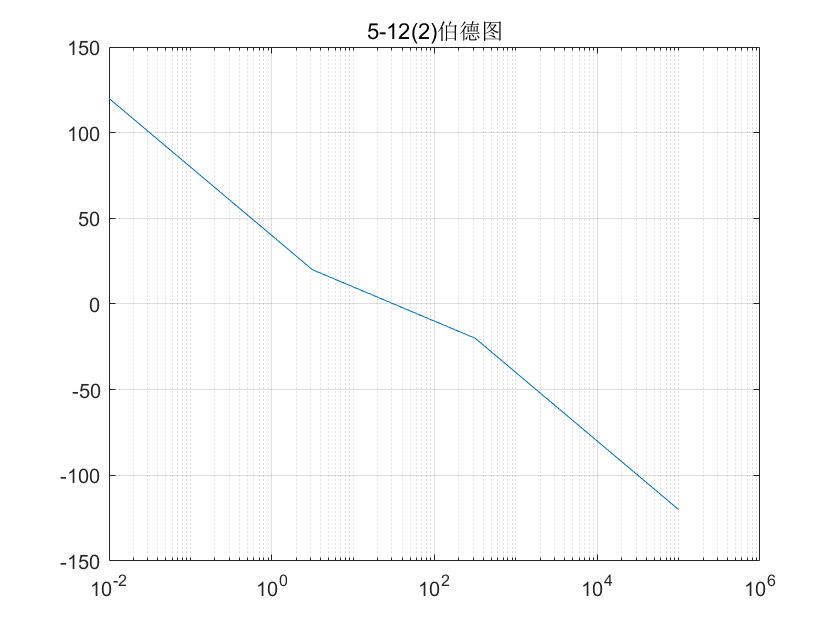

semilogx(x2,y2),grid on,title('5-12(2)伯德图');

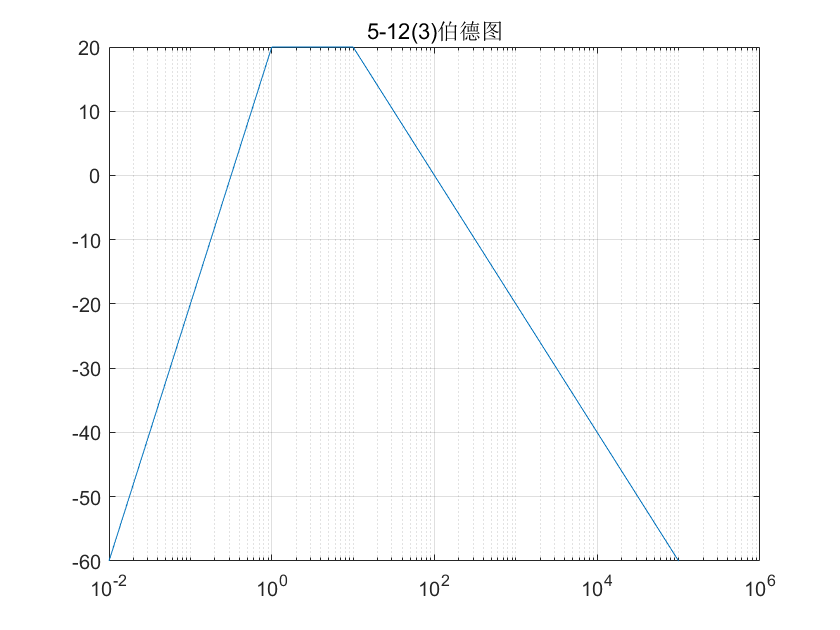

semilogx(x3,y3),grid on,title('5-12(3)伯德图');

% 5-13
clear
K= 1;
T1 = 1;
t1 = 2;
den11 = [T1 1 K*t1 K];

K= 1;
T2 = 2;
t2 = 2;
den12 = [T2 1 K*t2 K];

root11 = roots(den11)

root11 =   -0.2151 + 1.3071i
  -0.2151 - 1.3071i
  -0.5698 + 0.0000i


root12 = roots(den12)

root12 =    0.0000 + 1.0000i
   0.0000 - 1.0000i
  -0.5000 + 0.0000i



den21 = [1 3 2 1];
den22 = [1 3 2 0 1];
den23 = [1 3 2 0 0 1];
den24 = [1 3 2 0 0 0 1];
root21 = roots(den21)

root21 =   -2.3247 + 0.0000i
  -0.3376 + 0.5623i
  -0.3376 - 0.5623i


root22 = roots(den22)

root22 =   -1.6924 + 0.3181i
  -1.6924 - 0.3181i
   0.1924 + 0.5479i
   0.1924 - 0.5479i


root23 = roots(den23)

root23 =   -2.0985 + 0.0000i
  -0.8683 + 0.6219i
  -0.8683 - 0.6219i
   0.4175 + 0.4934i
   0.4175 - 0.4934i


root24 = roots(den24)

root24 =   -1.9200 + 0.0000i
  -1.4228 + 0.0000i
  -0.3758 + 0.7778i
  -0.3758 - 0.7778i
   0.5472 + 0.4372i
   0.5472 - 0.4372i


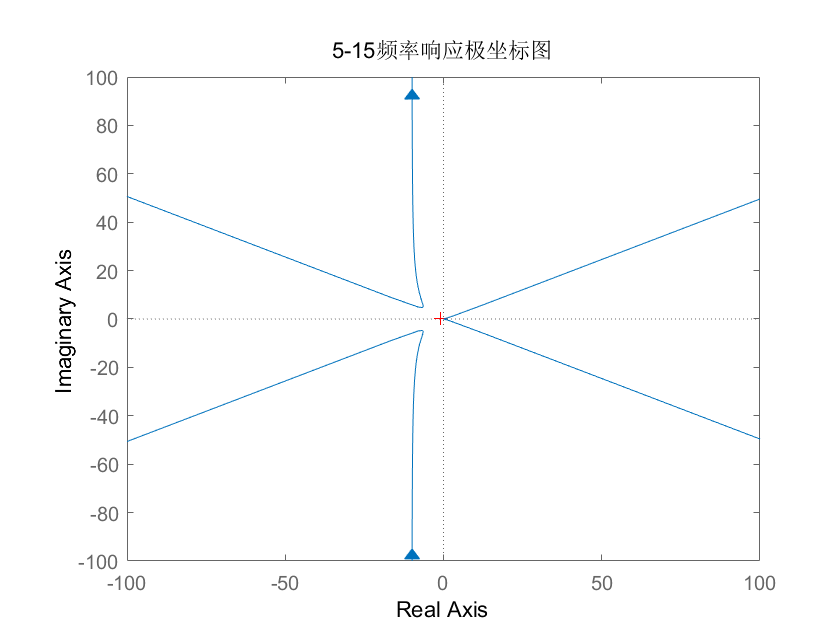


% 5-15
clear
G0 = tf([10],[0.25 0.25 1 1 0]);
nyquist(G0);
axis([-10e1 +10e1 -10e1 +10e1]);
title('5-15频率响应极坐标图');

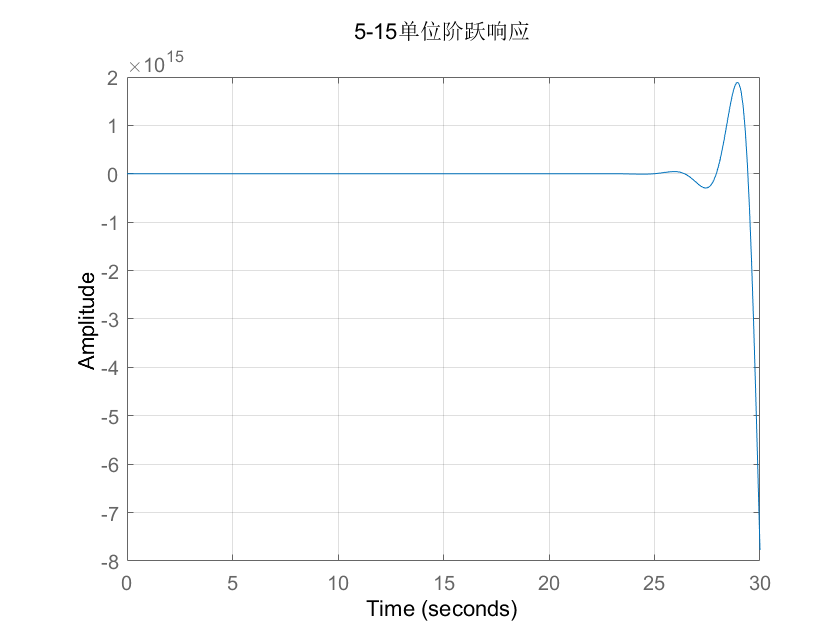


G = feedback(G0,1);
t = 0:0.1:30;
step(G,t),grid on;
title('5-15单位阶跃响应');

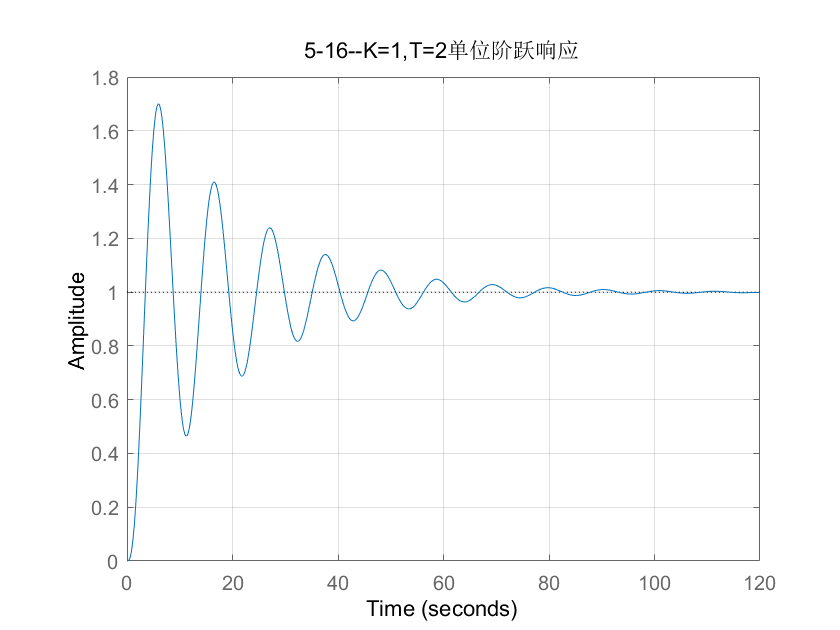

% 5-16
clear
K1 = 1;
T1 = 2;
G1 = tf([K1],[conv([conv([1 0],[T1,1])],[1 1])]);
G11 = feedback(G1,1);
K2 = 2;
T2 =0.5;
G2 = tf([K2],[conv([conv([1,0],[T2,1])],[1,1])]);
G21 = feedback(G2,1);
K3 = 10;
T3 = 0.1;
G3 = tf([K3],[conv([conv([1 0],[T3,1])],[1 1])]);
G31 = feedback(G3,1);
step(G11),grid on,title('5-16--K=1,T=2单位阶跃响应');

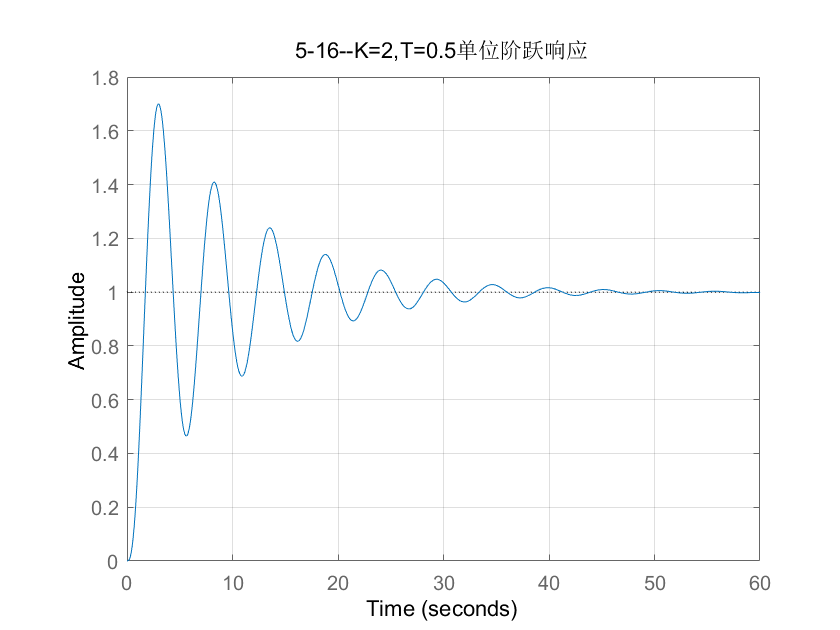

step(G21),grid on,title('5-16--K=2,T=0.5单位阶跃响应');

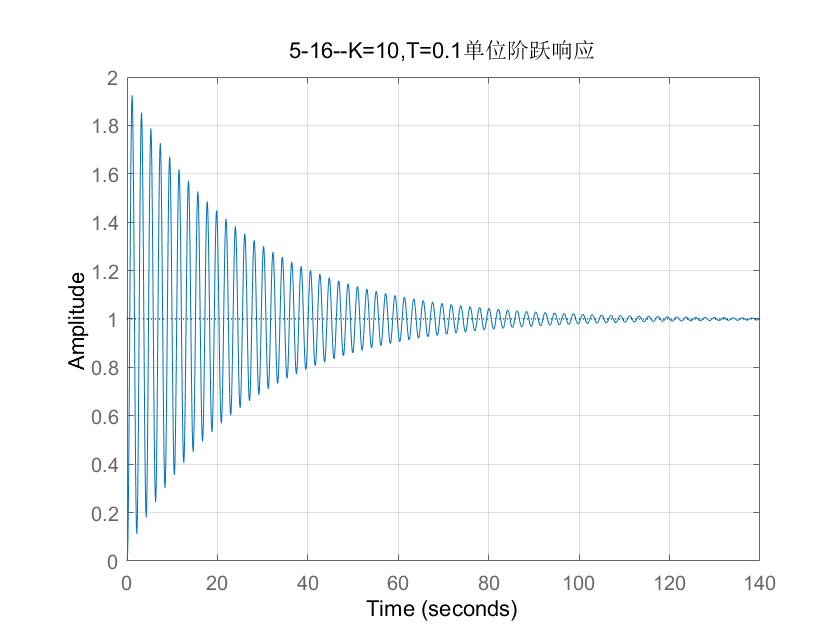

step(G31),grid on,title('5-16--K=10,T=0.1单位阶跃响应');

% 5-17
clear
G = tf([1 1],[conv([0.5 1 0],[1/9 1/3 1])]);
[Gm,Pm,wx,wc] = margin(G)

Gm = 2.2104

Pm = 69.3669

wx = 3.3996

wc = 1.6986

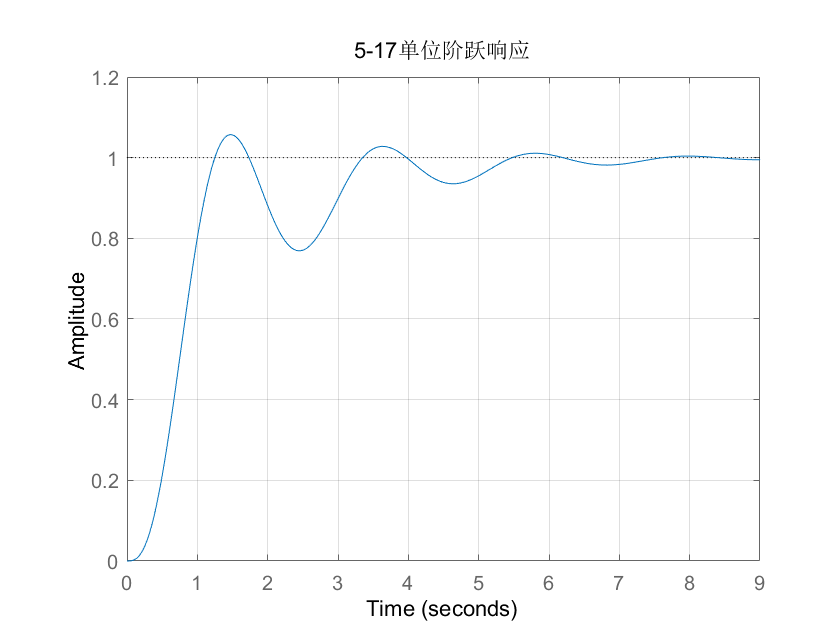

G1 = feedback(G,1);
step(G1),grid on;
title('5-17单位阶跃响应');

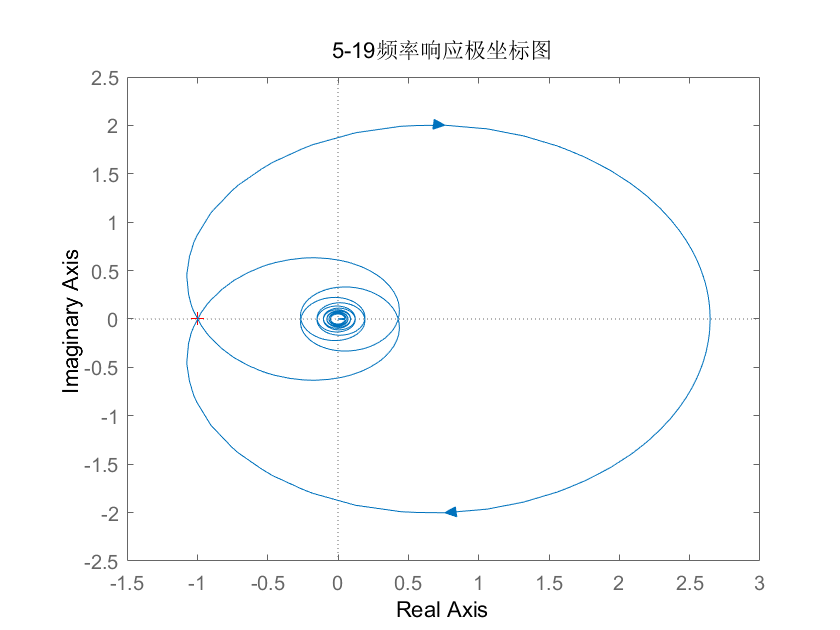

% 5-19
clear
w0 = 0.001;
while(-0.8*w0-atan(w0)>-pi)
    w0 = w0 + 0.001;
end
w = w0;
k = sqrt(1+w^2);
G = tf([k],[1 1],'inputdelay',0.8);
nyquist(G);
title('5-19频率响应极坐标图')

% 附录子程序

% function [wpos,ypos]=bd_asymp(G,w)
% G1=zpk(G); Gtf=tf(G);
% if nargin==1,
%     w=freqint2(Gtf.num{1},Gtf.den{1},100);
% end
% zer=G1.z{1}; pol=G1.p{1}; gain=G1.k;
% wpos=[]; pos1=[];
% for i=1:length(zer);
%     if isreal(zer(i))
%         wpos=[wpos, abs(zer(i))];
%         pos1=[pos1,20];
%     else
%         if imag(zer(i))>0
%             wpos=[wpos, abs(zer(i))];
%             pos1=[pos1,40];
%         end
%     end
% end
% for i=1:length(pol);
%     if isreal(pol(i))
%         wpos=[wpos, abs(pol(i))];
%         pos1=[pos1,-20];
%     else
%         if imag(pol(i))>0
%             wpos=[wpos, abs(pol(i))];
%             pos1=[pos1,-40];
%         end
%     end
% end
% wpos=[wpos w(1) w(length(w))];
% pos1=[pos1,0,0];
% [wpos,ii]=sort(wpos); pos1=pos1(ii);
% ii=find(abs(wpos)<eps); kslp=0;
% w_start=1000*eps;
% if length(ii)>0,
%     kslp=sum(pos1(ii));
%     ii=(ii(length(ii))+1):length(wpos);
%     wpos=wpos(ii); pos1=pos1(ii);
% end
% while 1
%     [ypos1,pp]=bode(G,w_start);
%     if isinf(ypos1), w_start=w_start*10;
%     else
%         break; 
%     end
% end
% wpos=[w_start wpos];
% ypos(1)=20*log10(ypos1);
% pos1=[kslp pos1];
% for i=2:length(wpos)
%     kslp=sum(pos1(1:i-1));
%     ypos(i)=ypos(i-1)+...
%     kslp*log10(wpos(i)/wpos(i-1));
% end
% ii=find(wpos>=w(1)&wpos<=w(length(w)));
% wpos=wpos(ii); ypos=ypos(ii);
% end